# `PROJECT #1`

# `PID GAIN ESTIMATION USING KALMAN FILTERING`

`ENPM : 667 CONTROL OF ROBOTIC SYSTEMS`

`NAME: ADITYA VAISHAMPAYAN`

`UID: 116077354`

`EMAIL: adityav@terpmail.umd.edu`

`CONTACT NO: +1-(240)-743-0530`

clc;
close all;


## **INPUT OUTPUT & REFERENCE SIGNALS **

% values of time for input
t_input = [0 0.1 0.2 0.3 0.4 0.5 0.51 0.6 0.7 0.8 0.9 1.0 1.01 1.1 1.2 1.3 1.4 1.5 1.51 1.6 1.7 1.8 1.9 2.0];
% values of input u
u_input = [0 31 7 10 10 10 18 15 15 15 15 15 7 10 10 10 10 10 18 15 15 15 15 15];


% values of time for output
t_output = [0 0.1 0.2 0.3 0.4 0.5 0.51 0.6 0.7 0.8 0.9 1.0 1.01 1.1 1.2 1.3 1.4 1.5 1.51 1.6 1.7 1.8 1.9 2.0];
% values of output y;
y_output = [0 180 100 100 100 100 100 100 150 150 150 150 150 100 100 100 100 100 100 150 150 150 150 150];

%in the above vectors I have take time instants such as 0.51 1.01 1.51
%becuase of the step nature of the input signal as seen in figure 4 of the
%paper. Since we know that a real time input signal can't have two values
%for the same instant of time, i have taken a very small interval of 0.01
%second after the time instant so as to approximate a step change in the value of the signal.


%In order to generate the output from the reference model we have to give inputs values to it. Our reference model is 
% in transfer function form. There is a command in matlab LSIM that allows us to get the set of output values from a transfer function 
% given a set of input values however, the only condition for the LSIM coomand to work is that the time intervals given to the 
% LSIM function need to be evenly spaces. 

%value of time for reference output
t_reference2 = [0 0.1 0.2 0.3 0.4 0.5 0.6 0.7 0.8 0.9 1.0 1.1 1.2 1.3 1.4 1.5 1.6 1.7 1.8 1.9 2.0];
%values of reference output
r_output2 = [0 100 100 100 100 100 150 150 150 150 150 100 100 100 100 100 150 150 150 150 150];

%reason for taking reference output 2 is becuause lsim takes in only evenly
%spaced values. Since r_ref wasn't evenly spaced we couldn't use it to
%obtain the value which we can repeat for a particular time instant, we
%used refoututput 2

% value of time for reference output
t_reference = [0 0.1 0.2 0.3 0.4 0.5 0.51 0.6 0.7 0.8 0.9 1.0 1.01 1.1 1.2 1.3 1.4 1.5 1.51 1.6 1.7 1.8 1.9 2.0];
% reference signal r(k) with time approximation
r_output = [0 100 100 100 100 100 100 150 150 150 150 150 150 100 100 100 100 100 100 150 150 150 150 150];

%after feeding the reference input values to the transfer function, a reference output signal is generated which is later
%approximated to incorporate time itervals 0.51 1.01 and 1.51

% this is Y_multiplication_output i.e GMzinverse_rt = Y_multiplication_output
% values of time of the reference output siganl
t_GMzinverse_rt = [0 0.1 0.2 0.3 0.4 0.5 0.51 0.6 0.7 0.8 0.9 1.0 1.01 1.1 1.2 1.3 1.4 1.5 1.51 1.6 1.7 1.8 1.9 2.0];
% values of the output reference signal
GMzinverse_rt = [0.00 16985.77 24003.68 24042.14 24042.22 24042.22 24042.22 32535.11 36044.07 36063.29 36063.34 36063.34 36063.34 27570.45 24061.50 24042.27 24042.22 24042.22 24042.22 32535.11 36044.07 36063.29 36063.34 36063.34 ];


## PLOTTING INPUT OUTPUT AND REFERENCE SIGNALS

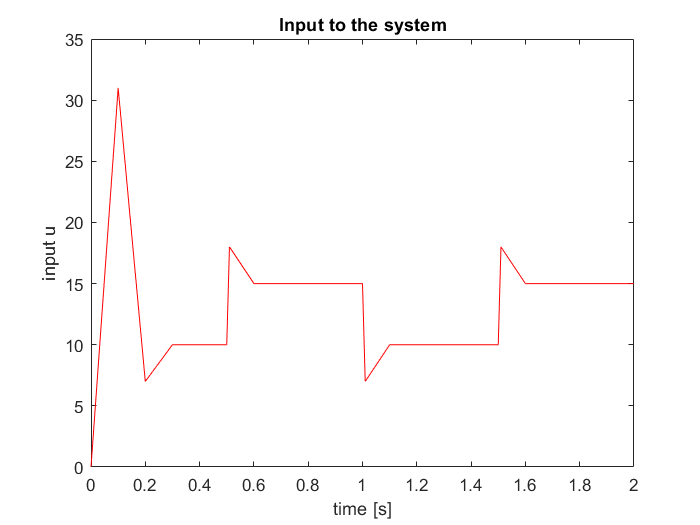

%------------------------PLOTTING INPUT SIGNAL-------------------
plot(t_input, u_input, 'Color','r');
title('Input to the system')
xlabel('time [s]');
ylabel('input u')

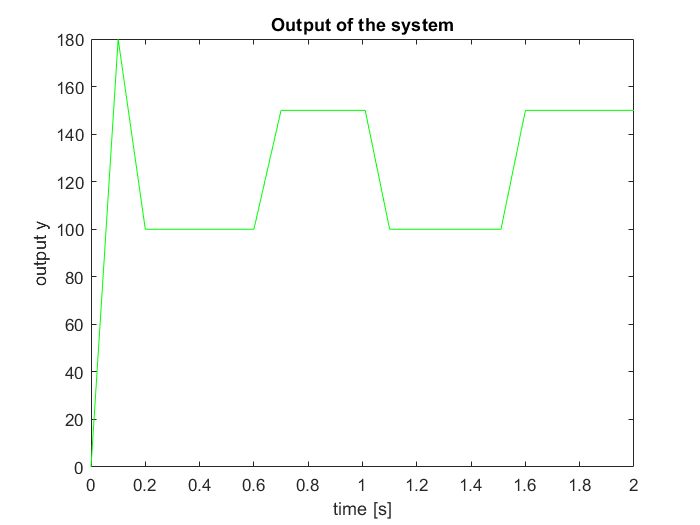

%-----------PLOTTING OUTPUT SIGNAL----------------
plot(t_output, y_output,'Color','g');
title('Output of the system');
xlabel('time [s]');
ylabel('output y');

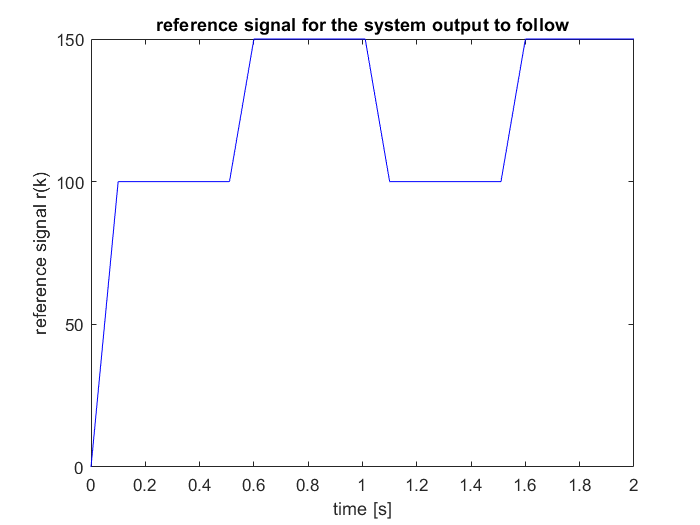

%-----------------PLOTTING REFERENCE SIGNAL r(k)----------------
% r(k) varies as follows:
%----------------r(k) = 100 (0<= t <= 0.5) & (1.0<= t<= 1.5)-----------
%----------------r(k) = 150 (0.5<= t <= 1) & (1.5<= t<= 2)-------------
plot(t_reference, r_output,'Color','b');
title('reference signal for the system output to follow')
xlabel('time [s]');
ylabel('reference signal r(k)')

## INITIALIZING VARIABLES FOR KALMAN FILTER


% we initialise the component of state vectors for kalman filter
syms a1 a2 a3;
% initialising PID gains
syms Kp Ki Kd;
% initialising terms for the kalman filter
syms theta_minus theta_initial P_minus K E ksi;

%state vector for kalman filter
theta = [a1; a2; a3];

%initital values of theta
theta_initial = [91.34; 
                 190.4; 
                -365.6];
             
%initial covariance matrix
P_initial = [100 0 0; 
             0 100 0; 
             0 0 100];
 
theta_predicted = [0; 0; 0];
       
b = [1;
     1;
     1];
 
BB_transpose = [1 1 1; 1 1 1; 1 1 1];

V = 0.00001;%variance of system nosie 
W = 0.00001;%variance of observation noise


ksi = [1;
       1;
       1];

syms theta_predicted Y_tilda 
syms Error Measured_Value P_predicted
syms output_index


## **GENERATING MODEL FOR THE REFERENCE OUTPUT**


%reference output 
syms p1 p2 mu rho sigma delta Ts sigma;

sigma = 0.030;% rise time in seconds [30 ms]
delta = 0; % damping coefficient [0]
Ts = 0.001; %Sampling interval in seconds [1 ms] 

rho = Ts/sigma ;
mu = 0.25*(1 - delta) + 0.51*delta;
p1 = -2*exp((-1*rho)/(2*mu)) * cos((sqrt(4*mu - 1)/(2*mu))*rho);
p2 = exp(-rho/mu);
num = [0 0.0042];
denum = [1 p1 p2];

%transfer function of the reference model in discrete form
G = filt(num,denum,Ts)


G =
 
          0.0042 z^-1
  ----------------------------
  1 - 1.871 z^-1 + 0.8752 z^-2
 
Sample time: 0.001 seconds
Discrete-time transfer function.



%conversion of discrete form to continuous form
G1 = d2c(G)


G1 =
 
     2.195 s + 4488
  --------------------
  s^2 + 133.3 s + 4444
 
Continuous-time transfer function.



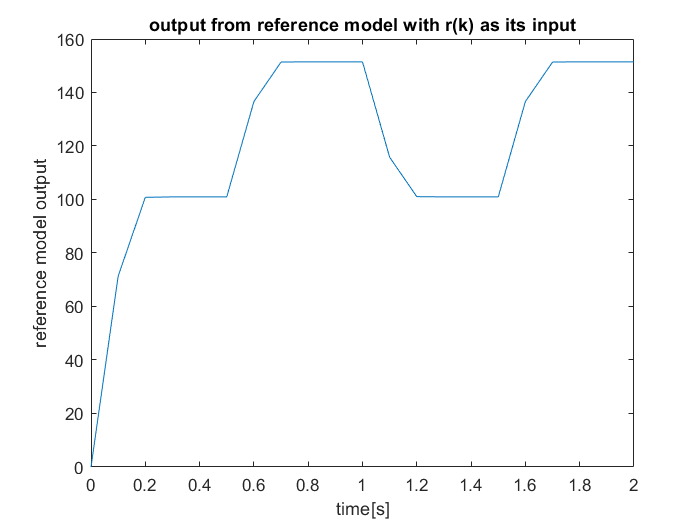

%reference output obtained from the reference model. We will compare our
%process output against the reference output
Y_multiplication_output = lsim(G1,r_output2,t_reference2);

%plotting output signal of the reference tf
plot(t_reference2,Y_multiplication_output)
title('output from reference model with r(k) as its input');
xlabel('time[s]');
ylabel('reference model output');

## INITIALIZING ARRAYS FOR Kp Ki and Kd to store their values

%storing Kp Ki Kd in an array;
ValueofKp = zeros(1,24);
ValueofKi = zeros(1,24);
ValueofKd = zeros(1,24);


## KALMAN FILTERING PROCESS

%initialising counter
output_index = 1;

%here for loop iterates 24 times. length(t_input) is 24 and t_input signify
%the time intervals
for i = 1:1:length(t_input)
    
    %----------------------INITIAL STATE AND COVARIANCE MATRICES-----------------------
    
    %taking initial values of state vector where theta_minus is that state
    %vector made of [a1;a2;a3]
    theta_minus = theta_initial;
    
    %P_minus is the covariance matrix
    %formula for calculating the covariance matrix
    P_minus = P_initial + V*diag(BB_transpose); 
    
    %--------------------KALMAN FILTERING PROCEDURE--------------------
    
    %calculating kalman Gain
    K = (P_minus * ksi)/((ksi' * P_minus*ksi) + W);    
    
    %in the paper the author is taking the difference of the actual output
    %signal with the output of the reference model thus generating an error signal. This error function is
    %called as the innovation which gets later fed back to the kalman filter.
    
    %calculaing the error "innovation"
    %y_output(i) is the output of the system at ith instant of time
    %GMzinverse(i) is the output of the reference model at ith instant of time
    Error = y_output(i) - GMzinverse_rt(i);
    
    %incrementing the output index for the next iteration
    output_index = output_index + 1;
    
    %---------------------------PREDICTING THE NEW STATE VECTOR----------------------------
    %predicted the new state vector
    theta_predicted = theta_minus + (K*Error);
    
    %-------------------PREDICTING THE NEW COVARIANCE MATRIX-------------
    
    %updating the new covariance matrix
    P_predicted = (eye(3) - K*ksi')*P_minus;
    
    %-----------OBTAINING THE VALUES OF Kp Ki Kd FROM CONTROL----------------
    %--------------PARAMETERS a1 a2 and a3---------------------
    
    %obtaining PID gains from state vectors
    Kp = (2*theta_minus(2) + theta_minus(3)-2)/theta_minus(1);
    Ki = 1/theta_minus(1);
    Kd = (1 - theta_minus(2) - theta_minus(3))/theta_minus(1);

    %storing value of Kp Kd Ki in an array      
    ValueofKp(i) = Kp;
    ValueofKd(i) = Kd;
    ValueofKi(i) = Ki;
    
    %--------UPDATING STATE AND COVARIANCE MATRICES FOR NEXT CYCLE-----
    
    %updating the values for the next cycle
    theta_initial = theta_predicted;
    P_initial = P_predicted;
   
end


## PLOTTING Kp Ki AND Kd GAINS

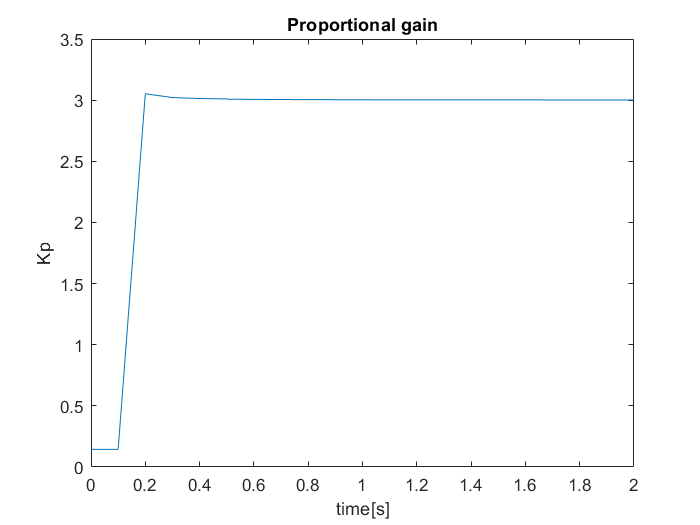

%because of lack of data, i had to make up approximated data and hence the
%pid gains arent the same as outhors. But we can see that the theoritical PID gains
%are getting stabilised over time and hence i was able to stabilise the
%system using just the input output data without obtaining the transfer
%function or model of the system

%-----------plotting Kp----------
plot(t_output,ValueofKp)
title('Proportional gain');
xlabel('time[s]');
ylabel('Kp');

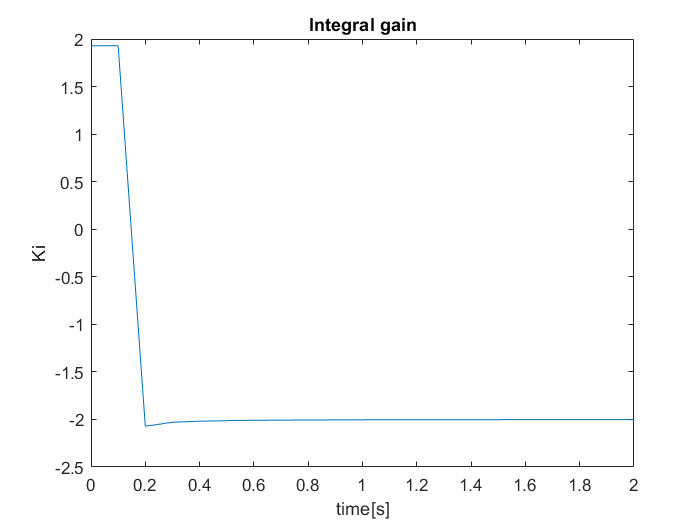

%---------plotting Ki------------
plot(t_output,ValueofKd);
title('Integral gain');
xlabel('time[s]');
ylabel('Ki');

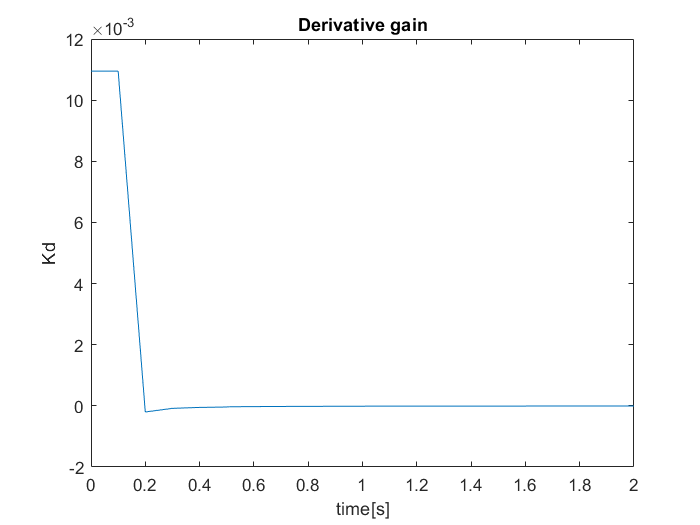

%------plotting kd---------
plot(t_output,ValueofKi)
title('Derivative gain');
xlabel('time[s]');
ylabel('Kd');